# [Additive Manufacturing](https://apmonitor.com/pds/index.php/Main/AdditiveManufacturing)

Additive manufacturing is the process of building from a computer controlled 3-dimensional printer. The material can be polymer (plastic), ceramic, metallic powder, liquid, or any material that is joined together through deposition, solidification, or fusion. It speeds the development of prototypes by precisely converting a computer aided design (CAD) drawing into a physical device. Additive manufacturing can be either a prototype or scaled up to full product production, but typically for applications that require customization or with low production volumes.

**Background:** A [3D print data set of additive manufacturing test conditions](https://apmonitor.com/pds/uploads/Main/manufacturing.txt) is available for Polylactic Acid (PLA) and Acrylonitrile Butadiene Styrene (ABS). PLA can print at lower temperatures of 180°C compared to 250°C for ABS. PLA is more brittle than ABS and is not typically suitable for high strength applications. The data was collected by researchers in the Mechanical Engineering department at Selçuk Üniversitesi on a Ultimaker S5 3D printer. The study focused on how the parameters in a specific 3D printer affects the print quality, accuracy and final part strength. This work is based on the settings and PLA or ABS filaments. Material and strength tests were carried out on a Sincotec GMBH tester capable of pulling 20 kN.

Nine parameters were adjusted for the Ultimaker S5 3D printer.

- Layer Height (mm)

- Wall Thickness (mm)

- Infill Density (%)

- Infill Pattern (Honeycomb or Grid)

- Nozzle Temperature (ºC)

- Bed Temperature (ºC)

- Print Speed (mm/s)

- Material (PLA or ABS)

- Fan Speed (%)

After the part was manufactured, three parameters were measured for each product.

- Roughness (µm)

- Tension Strength (MPa)

- Elongation (%)

The labeled data is a combination of PLA and ABS material, print patterns, and conditions with 66 samples from a first repository and 50 samples from a second repository. The [combined set](https://apmonitor.com/pds/uploads/Main/manufacturing.txt) is 70 samples with the duplicates removed and one outlier added. The label associated with each filament is *pla* or *abs*. The print pattern is *grid* or *honeycomb*. [One-hot encoding](https://en.wikipedia.org/wiki/One-hot) translates character labels into a binary representation (0 or 1) for classification.

 [Additive Manufacturing Data](https://apmonitor.com/pds/uploads/Main/manufacturing.txt)

## Part 1: Data Visualization and Cleansing

Generate summary statistics with a profiling report to [statistically characterize the data](https://apmonitor.com/pds/index.php/Main/StatisticsMath). Use box plots to identify the one outlier in the data. Remove the row that contains the outlier from the data set. Generate a pair plot and correlation matrix. What factors are highly correlated to *Material (PLA or ABS)* and *Tension Strength (MPa)*?

% Clear preceeding data 
clear;
% Load data from URL 
url = "https://apmonitor.com/pds/uploads/Main/manufacturing.txt";
data = readtable(url);

% Change and store variable names
parameters = ["Layer Height" "Wall Thickness" "Infill Density" ...
            "Infill Pattern" "Nozzle Temperature" "Bed Temperature" ...
            "Print Speed" "Material" "Fan Speed" ...
            "Roughness" "Tension Strength" "Elongation"];
data.Properties.VariableNames = parameters;

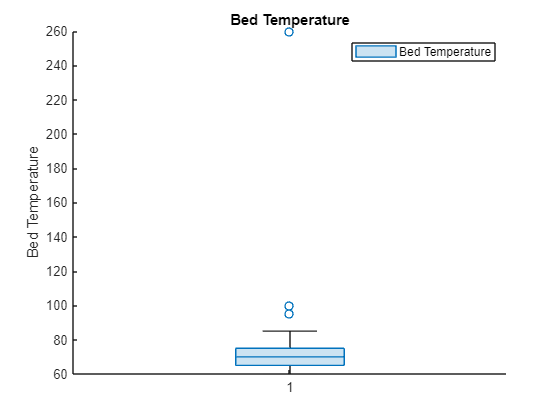

% Create boxchart of data.("Bed Temperature")
h2 = boxchart(data.("Bed Temperature"),"DisplayName","Bed Temperature");

% Add ylabel, title, and legend
ylabel("Bed Temperature")
title("Bed Temperature")
legend

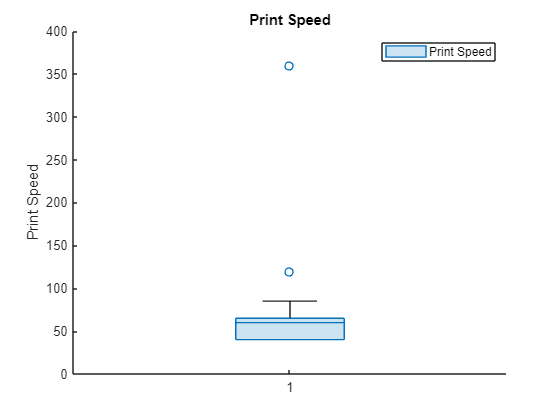

% Create boxchart of data.("Print Speed")
h = boxchart(data.("Print Speed"),"DisplayName","Print Speed");

% Add ylabel, title, and legend
ylabel("Print Speed")
title("Print Speed")
legend


% Fill outliers
[cleaned, TFrm] = rmoutliers(data.("Bed Temperature"),"percentiles",[5 95]);

data_clean = data(~TFrm,:);

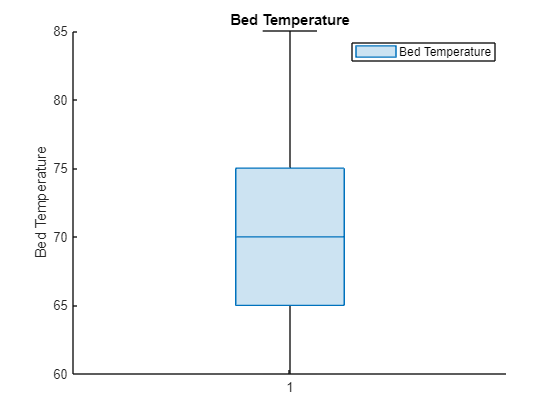

% Create boxchart of data_clean.("Bed Temperature")
h3 = boxchart(data_clean.("Bed Temperature"),"DisplayName","Bed Temperature");

% Add ylabel, title, and legend
ylabel("Bed Temperature")
title("Bed Temperature")
legend

data_clean.Material = categorical(data_clean.Material, {'abs','pla'},{'0','1'});
data_clean.Material=double(data_clean.Material);
data_clean.("Infill Pattern") = categorical(data_clean.("Infill Pattern"), {'grid','honeycomb'},{'0','1'});
data_clean.("Infill Pattern") = double(data_clean.("Infill Pattern"));

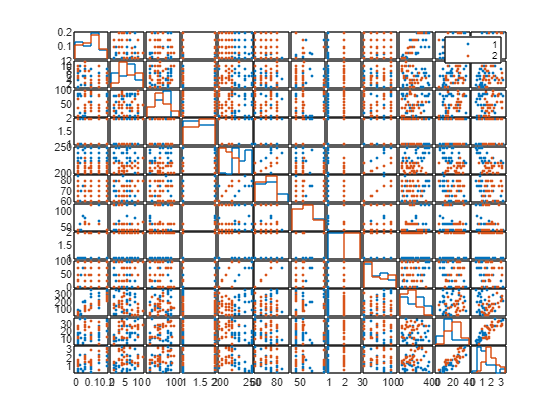

% Generate a pair plot 
figure;
gplotmatrix(table2array(data_clean),[], data_clean.Material)

% Print Statistics Values
for i = 1:numel(parameters)
    parameter = parameters{i};
    disp(parameter)
    disp(statistics(data_clean.(parameter)))
end

Layer Height


    count: 67
     mean: 0.0982
      std: 0.0621
      min: 0.0200
      max: 0.2000
       Q1: 0.0525
       Q2: 0.1000
       Q3: 0.1500



Wall Thickness


    count: 67
     mean: 5.4701
      std: 2.9681
      min: 1
      max: 12
       Q1: 3
       Q2: 6
       Q3: 8



Infill Density


    count: 67
     mean: 53.0149
      std: 27.4924
      min: 10
      max: 100
       Q1: 30
       Q2: 50
       Q3: 80



Infill Pattern


    count: 67
     mean: 1.5224
      std: 0.5033
      min: 1
      max: 2
       Q1: 1
       Q2: 2
       Q3: 2



Nozzle Temperature


    count: 67
     mean: 221.5672
      std: 14.7250
      min: 200
      max: 250
       Q1: 210
       Q2: 220
       Q3: 230



Bed Temperature


    count: 67
     mean: 69.7015
      std: 7.2760
      min: 60
      max: 85
       Q1: 65
       Q2: 70
       Q3: 75



Print Speed


    count: 67
     mean: 65.0746
      std: 29.1871
      min: 40
      max: 120
       Q1: 40
       Q2: 60
       Q3: 63.7500



Material


    count: 67
     mean: 1.4776
      std: 0.5033
      min: 1
      max: 2
       Q1: 1
       Q2: 1
       Q3: 2



Fan Speed


    count: 67
     mean: 48.1791
      std: 35.6778
      min: 0
      max: 100
       Q1: 25
       Q2: 50
       Q3: 75



Roughness


    count: 67
     mean: 159.3134
      std: 95.6668
      min: 21
      max: 368
       Q1: 75
       Q2: 145
       Q3: 220



Tension Strength


    count: 67
     mean: 19.7015
      std: 8.8950
      min: 4
      max: 37
       Q1: 12
       Q2: 18
       Q3: 27



Elongation


    count: 67
     mean: 1.6269
      std: 0.7523
      min: 0.4000
      max: 3.3000
       Q1: 1.1000
       Q2: 1.5000
       Q3: 2.1000



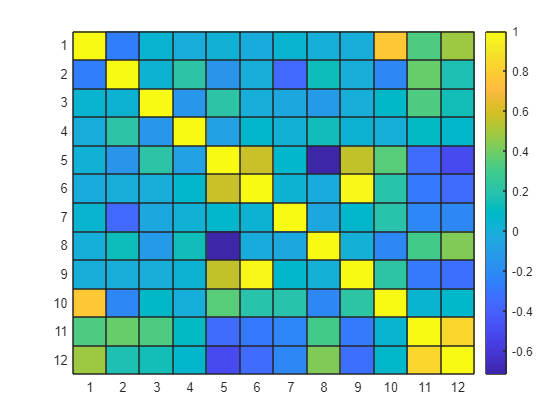

% Create correlation matrix 
R = corrcoef(table2array(data_clean));

% Plot the heat map
figure;
heatmap(R,'Colormap',parula)

## Part 2: Prediction and Analysis

Examination of a Spearman's "rho" based correlation matrix versus the one presented above based on R^2 values shows little change. We are primarily interested in predicting material and tension strength. For material, nozzle temperature and elongation seem to have the strongest correlations. For tension strength the strongest correlates are layer height, nozzle temperature, and material; disregarding elongation as it is not a specifiable machine input.

% Scale Data 
sc_data = rescale(table2array(data_clean))

sc_data =     0.0001    0.0217    0.2446    0.0027    0.5978    0.1630    0.1087    0.0027         0    0.0679    0.0489    0.0033
    0.0001    0.0190    0.2446    0.0054    0.6114    0.1766    0.1087    0.0027    0.0679    0.0870    0.0435    0.0038
    0.0001    0.0027    0.2174    0.0027    0.6250    0.1902    0.1087    0.0027    0.1359    0.1087    0.0217    0.0022
    0.0001    0.0109    0.1902    0.0054    0.6522    0.2038    0.1087    0.0027    0.2038    0.1848    0.0272    0.0014
    0.0001    0.0163    0.2446    0.0027    0.6793    0.2174    0.1087    0.0027    0.2717    0.2500    0.0136    0.0019
    0.0001    0.0272    0.1087    0.0054    0.5435    0.1630    0.1087    0.0054         0    0.1630    0.0652    0.0030
    0.0001    0.0136    0.0272    0.0027    0.5571    0.1766    0.1087    0.0054    0.0679    0.1495    0.0326    0.0035
    0.0001    0.0272    0.0272    0.0054    0.5707    0.1902    0.1087    0.0054    0.1359    0.0571    0.0380    0.0041
    0.0001    0.0245  

% Make the array into a table again
sc_data = array2table(sc_data)

sc_data = 67×12 table
     sc_data1     sc_data2     sc_data3    sc_data4     sc_data5    sc_data6    sc_data7    sc_data8     sc_data9    sc_data10    sc_data11    sc_data12
    __________    _________    ________    _________    ________    ________    ________    _________    ________    _________    _________    _________

    5.4348e-05     0.021739     0.24457    0.0027174    0.59783     0.16304      0.1087     0.0027174           0    0.067935     0.048913     0.0032609
    5.4348e-05     0.019022     0.24457    0.0054348    0.61141     0.17663      0.1087     0.0027174    0.067

% Rename the variables with the correct names
sc_data.Properties.VariableNames = data_clean.Properties.VariableNames

sc_data = 67×12 table
    Layer Height    Wall Thickness    Infill Density    Infill Pattern    Nozzle Temperature    Bed Temperature    Print Speed    Material     Fan Speed    Roughness    Tension Strength    Elongation
    ____________    ______________    ______________    ______________    __________________    _______________    ___________    _________    _________    _________    ________________    __________

     5.4348e-05        0.021739           0.24457         0.0027174            0.59783              0.16304           0.1087      0.0027174           0     0.067935     

% Implement 80/20 train/test
[r,c] = size(sc_data) % Get the number of rows and columns

r = 67

c = 12

cv = cvpartition(r,'HoldOut',0.20); % Create a partition to split the data
idx = cv.test; % Get the testing index

% Assign testing and training data
trainData = sc_data(~idx,:);
testData = sc_data(idx,:);

% Use chi-squared statistic to find the importance of each feature in
% predicting the Material
Z_score = fscchi2(trainData,trainData.Material)

Z_score =      8     5    12    11     2     3     4    10     7     1     9     6


% Make the variable names categorical for plotting
X = categorical(trainData.Properties.VariableNames)

X = 1×12 categorical array
     Layer Height      Wall Thickness      Infill Density      Infill Pattern      Nozzle Temperature      Bed Temperature      Print Speed      Material      Fan Speed      Roughness      Tension Strength      Elongation 


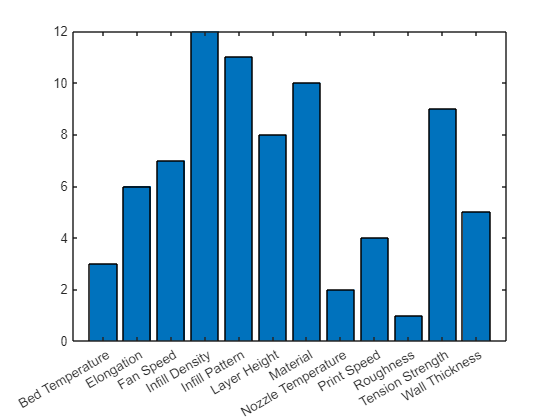

% Plot Z scores
bar(X,Z_score)

tiledlayout(4,2)

% Perform predictions using various machine learning algorithms
% Naive Bayes
nb = fitcnb(trainData, 'Material')

nb =   ClassificationNaiveBayes
            PredictorNames: {'Layer Height'  'Wall Thickness'  'Infill Density'  'Infill Pattern'  'Nozzle Temperature'  'Bed Temperature'  'Print Speed'  'Fan Speed'  'Roughness'  'Tension Strength'  'Elongation'}
              ResponseName: 'Material'
     CategoricalPredictors: []
                ClassNames: [0.0027 0.0054]
            ScoreTransform: 'none'
           NumObservations: 54
         DistributionNames: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
    DistributionParameters: {2×11 cell}


  Properties, Methods


labels = predict(nb, testData);
nexttile
confusionchart(testData.Material,labels)
title("Naive Bayes Prediction")

% Nearest Neighbors
knn = fitcknn(trainData,'Material')

knn =   ClassificationKNN
           PredictorNames: {'Layer Height'  'Wall Thickness'  'Infill Density'  'Infill Pattern'  'Nozzle Temperature'  'Bed Temperature'  'Print Speed'  'Fan Speed'  'Roughness'  'Tension Strength'  'Elongation'}
             ResponseName: 'Material'
    CategoricalPredictors: []
               ClassNames: [0.0027 0.0054]
           ScoreTransform: 'none'
          NumObservations: 54
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


labels = predict(knn, testData);
nexttile
confusionchart(testData.Material,labels)
title("Nearest Neighbors Prediction")

% Classification Tree
tree = fitctree(trainData,'Material')

tree =   ClassificationTree
           PredictorNames: {'Layer Height'  'Wall Thickness'  'Infill Density'  'Infill Pattern'  'Nozzle Temperature'  'Bed Temperature'  'Print Speed'  'Fan Speed'  'Roughness'  'Tension Strength'  'Elongation'}
             ResponseName: 'Material'
    CategoricalPredictors: []
               ClassNames: [0.0027 0.0054]
           ScoreTransform: 'none'
          NumObservations: 54


  Properties, Methods


labels = predict(tree, testData);
nexttile
confusionchart(testData.Material,labels)
title("Classification Tree Prediction")

% Discriminant Analysis
disc = fitcdiscr(trainData, 'Material')

disc =   ClassificationDiscriminant
           PredictorNames: {'Layer Height'  'Wall Thickness'  'Infill Density'  'Infill Pattern'  'Nozzle Temperature'  'Bed Temperature'  'Print Speed'  'Fan Speed'  'Roughness'  'Tension Strength'  'Elongation'}
             ResponseName: 'Material'
    CategoricalPredictors: []
               ClassNames: [0.0027 0.0054]
           ScoreTransform: 'none'
          NumObservations: 54
              DiscrimType: 'linear'
                       Mu: [2×11 double]
                   Coeffs: [2×2 struct]


  Properties, Methods


labels = predict(disc, testData);
nexttile
confusionchart(testData.Material,labels)
title("Discriminant Analysis Prediction")

% Support Vector Machine Classification
vect = fitcsvm(trainData,'Material')

vect =   ClassificationSVM
           PredictorNames: {'Layer Height'  'Wall Thickness'  'Infill Density'  'Infill Pattern'  'Nozzle Temperature'  'Bed Temperature'  'Print Speed'  'Fan Speed'  'Roughness'  'Tension Strength'  'Elongation'}
             ResponseName: 'Material'
    CategoricalPredictors: []
               ClassNames: [0.0027 0.0054]
           ScoreTransform: 'none'
          NumObservations: 54
                    Alpha: [47×1 double]
                     Bias: -0.3502
         KernelParameters: [1×1 struct]
           BoxConstraints: [54×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [54×1 logical]
                   Solver: 'SMO'


  Properties, Methods


labels = predict(vect, testData);
nexttile
confusionchart(testData.Material,labels)
title("Support Vector Machine Prediction")

% Classification Ensemble
ensemble = fitcensemble(trainData,'Material')

ensemble =   ClassificationEnsemble
           PredictorNames: {'Layer Height'  'Wall Thickness'  'Infill Density'  'Infill Pattern'  'Nozzle Temperature'  'Bed Temperature'  'Print Speed'  'Fan Speed'  'Roughness'  'Tension Strength'  'Elongation'}
             ResponseName: 'Material'
    CategoricalPredictors: []
               ClassNames: [0.0027 0.0054]
           ScoreTransform: 'none'
          NumObservations: 54
               NumTrained: 100
                   Method: 'LogitBoost'
             LearnerNames: {'Tree'}
     ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                  FitInfo: [100×1 double]
       FitInfoDescription: {2×1 cell}


  Properties, Methods


labels = predict(ensemble, testData);
nexttile
confusionchart(testData.Material,labels)
title("Classification Ensemble Prediction")

% Neural Network
nn = fitcnet(trainData,'Material')

nn =   ClassificationNeuralNetwork
           PredictorNames: {'Layer Height'  'Wall Thickness'  'Infill Density'  'Infill Pattern'  'Nozzle Temperature'  'Bed Temperature'  'Print Speed'  'Fan Speed'  'Roughness'  'Tension Strength'  'Elongation'}
             ResponseName: 'Material'
    CategoricalPredictors: []
               ClassNames: [0.0027 0.0054]
           ScoreTransform: 'none'
          NumObservations: 54
               LayerSizes: 10
              Activations: 'relu'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [85×7 table]


  Properties, Methods


labels = predict(nn, testData);
nexttile
confusionchart(testData.Material,labels)
title("Neural Network Prediction")

% Generalized Additive Model
genadd = fitcgam(trainData,'Material')

genadd =   ClassificationGAM
           PredictorNames: {'Layer Height'  'Wall Thickness'  'Infill Density'  'Infill Pattern'  'Nozzle Temperature'  'Bed Temperature'  'Print Speed'  'Fan Speed'  'Roughness'  'Tension Strength'  'Elongation'}
             ResponseName: 'Material'
    CategoricalPredictors: []
               ClassNames: [0.0027 0.0054]
           ScoreTransform: 'logit'
                Intercept: -0.8432
          NumObservations: 54


  Properties, Methods


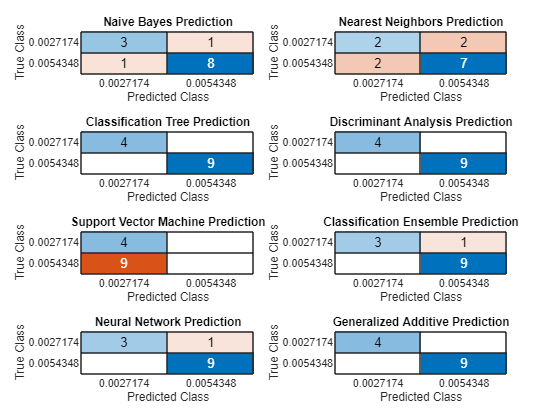

labels = predict(genadd, testData);
nexttile
confusionchart(testData.Material,labels)
title("Generalized Additive Prediction")

### **Regression Practice**

 Use 3 regression methods. Possible [regression methods](https://apmonitor.com/pds/notebooks/06_regression.html) are:

- [Linear Regression](https://apmonitor.com/pds/index.php/Main/LinearRegression)

- [Neural Network (Deep Learning)](https://apmonitor.com/pds/index.php/Main/MultilayerPerceptronNeuralNetwork)

- [K-Nearest Neighbors](https://apmonitor.com/pds/index.php/Main/KNearestNeighborsRegression)

- [Support Vector Regressor](https://apmonitor.com/pds/index.php/Main/SupportVectorRegressor)

- [XGBoost Regressor](https://apmonitor.com/pds/index.php/Main/XGBoostRegressor)

There is concern that PLA has less strength than ABS for additive manufacturing. Compare the PLA and ABS predicted strength for all of the test points. One way to compare the strength is to change the *PLA* material to *ABS* and recalculate the predicted *Tension Strength (MPa)*.

Examples chosen: Linear Regression, Neural Network, K-Nearest Neighbors 

% Use Tension strength data

% Obtain all data from layer_height to tension_strength
lm_input = trainData(:,1:11) 

lm_input = 54×11 table
    Layer Height    Wall Thickness    Infill Density    Infill Pattern    Nozzle Temperature    Bed Temperature    Print Speed    Material     Fan Speed    Roughness    Tension Strength
    ____________    ______________    ______________    ______________    __________________    _______________    ___________    _________    _________    _________    ________________

     5.4348e-05        0.021739           0.24457         0.0027174            0.59783              0.16304           0.1087      0.0027174           0     0.067935         0.048913    
     5.4348e-05        0.019022           0.

% Linear Regression 
mdl = fitlm(lm_input)

mdl = Linear regression model:
    Tension Strength ~ 1 + Layer Height + Wall Thickness + Infill Density + Infill Pattern + Nozzle Temperature + Bed Temperature + Print Speed + Material + Fan Speed + Roughness

Estimated Coefficients:
                          Estimate        SE        tStat        pValue  
                          _________    ________    ________    __________

    (Intercept)           -0.078018     0.13532    -0.57655       0.56725
    Layer Height             94.655       28.31      3.3435     0.0017219
    Wall Thickness           1.3573     0.35509      3.8223    0.00042121
    Infill Density          0.11654     0.03418      3.4097     0.0014244
    Infill Pattern            1.661      1.9355     0.85817       0.39556
    Nozzle Temper

% Make predictions using the model and test data
predictions = predict(mdl,testData(:,1:10))

predictions =     0.0314
    0.0585
    0.0125
    0.0901
    0.0380
    0.0577
    0.0535
    0.0559
    0.0338
    0.0314


% Get the R squared value between the predictions and the actual data
R_squared = rsq(table2array(testData(:,11)),predictions)

SSresid = 0.0025

SStotal = 0.0065

R_squared = 0.6160

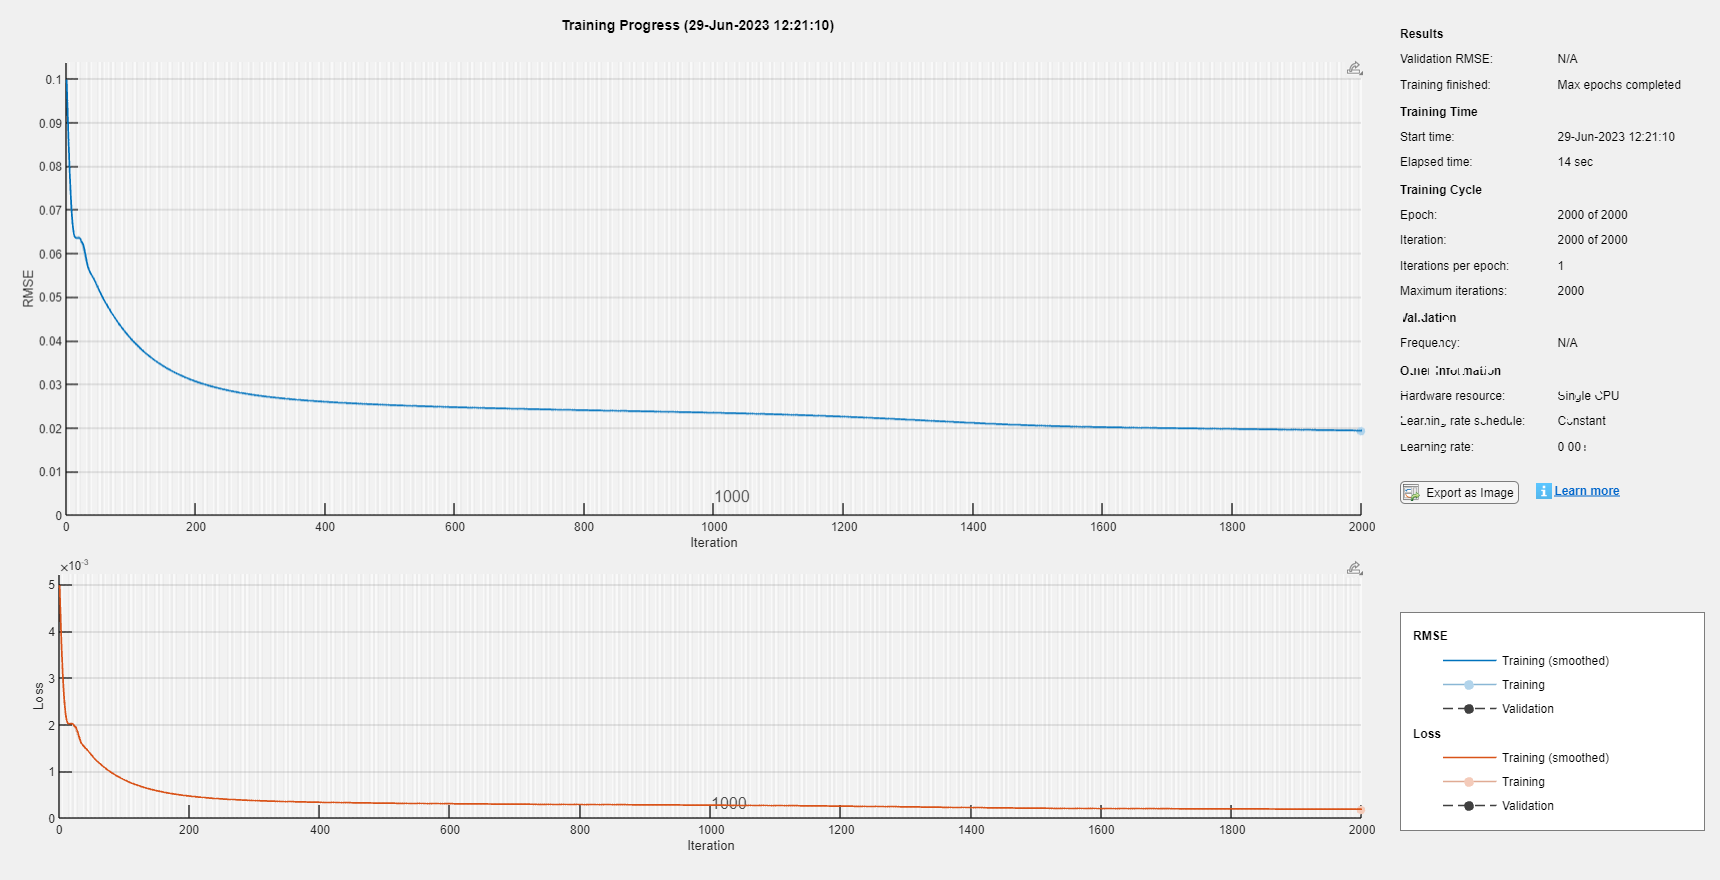

% Neural Network regressor
layers = [
    sequenceInputLayer(10,"Name","input")
    fullyConnectedLayer(2,"Name","fc_2")
    fullyConnectedLayer(2,"Name","fc")
    tanhLayer("Name","tanh")
    fullyConnectedLayer(2,"Name","fc_1")
    fullyConnectedLayer(1,"Name","fc_3")
    regressionLayer("Name","regressionoutput")];

% Set options for train 
options = trainingOptions("adam", ...
    MaxEpochs=2000, ...
    Verbose=false, ...
    Plots="training-progress");

% Train model to dataset 
net = trainNetwork(table2array(trainData(:,1:10))', table2array(trainData(:,11))', layers,options);

% Find R^2 for neural net 
y_val = predict(net,table2array(testData(:,1:10))');
R_squared_net = rsq(y_val',table2array(testData(:,11)))

SSresid = single
0.0034

SStotal = single
0.0032

R_squared_net = single
-0.0536

% Support Vector Regression 
mdl_vec = fitrsvm(trainData(:,1:10),trainData(:,11)) 

mdl_vec =   RegressionSVM
           PredictorNames: {'Layer Height'  'Wall Thickness'  'Infill Density'  'Infill Pattern'  'Nozzle Temperature'  'Bed Temperature'  'Print Speed'  'Material'  'Fan Speed'  'Roughness'}
             ResponseName: 'Tension Strength'
    CategoricalPredictors: []
        ResponseTransform: 'none'
                    Alpha: [47×1 double]
                     Bias: 0.1886
         KernelParameters: [1×1 struct]
          NumObservations: 54
           BoxConstraints: [54×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [54×1 logical]
                   Solver: 'SMO'


  Properties, Methods


% Make predictions using the model and test data
pred_vec = predict(mdl_vec,testData(:,1:10))

pred_vec =     0.0446
    0.0432
    0.0303
    0.0791
    0.0601
    0.0446
    0.0642
    0.0442
    0.0239
    0.0491


% Find the R squared value between the predictions and actual data
R_squared_net = rsq(pred_vec,table2array(testData(:,11)))

SSresid = 0.0045

SStotal = 0.0034

R_squared_net = -0.3279

% Graph data
figure
testData_graph = table2array(testData(:,11))

testData_graph =     0.0326
    0.0734
    0.0272
    0.0734
    0.0625
    0.0707
    0.0299
    0.0489
    0.0380
    0.0245


scatter(testData_graph,table2array(testData(:,11)))
hold

Current plot held


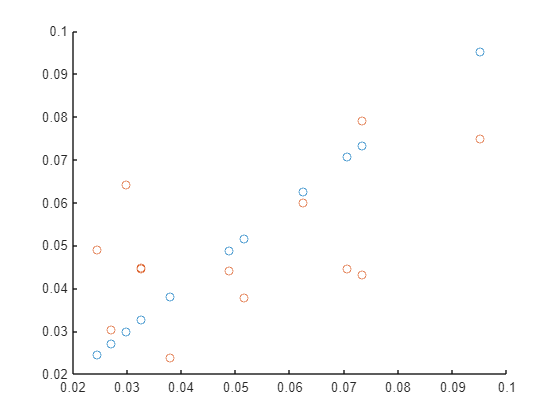

scatter(testData_graph,pred_vec)

% Recalculate predicted vals for PLA if changed to ABS
dfPl = (testData.Material < 0.005) == 0 

dfPl = 13×1 logical array
   1
   1
   0
   1
   1
   1
   1
   1
   1
   0


test_Pl = testData(dfPl,:)

test_Pl = 9×12 table
    Layer Height    Wall Thickness    Infill Density    Infill Pattern    Nozzle Temperature    Bed Temperature    Print Speed    Material     Fan Speed    Roughness    Tension Strength    Elongation
    ____________    ______________    ______________    ______________    __________________    _______________    ___________    _________    _________    _________    ________________    __________

     5.4348e-05        0.013587          0.027174         0.0027174            0.55707              0.17663           0.1087      0.0054348    0.067935      0.14946      

% Run three tests on Pla materials 
pl_net_pred = predict(net,table2array(test_Pl(:,1:10))');
predictions_pl = predict(mdl,test_Pl(:,1:10))

predictions_pl =     0.0314
    0.0585
    0.0901
    0.0380
    0.0577
    0.0535
    0.0559
    0.0338
    0.0348


pred_vec_pl = predict(mdl_vec,test_Pl(:,1:10))

pred_vec_pl =     0.0446
    0.0432
    0.0791
    0.0601
    0.0446
    0.0642
    0.0442
    0.0239
    0.0449


% Now do it for Abs 
test_Ab = test_Pl

test_Ab = 9×12 table
    Layer Height    Wall Thickness    Infill Density    Infill Pattern    Nozzle Temperature    Bed Temperature    Print Speed    Material     Fan Speed    Roughness    Tension Strength    Elongation
    ____________    ______________    ______________    ______________    __________________    _______________    ___________    _________    _________    _________    ________________    __________

     5.4348e-05        0.013587          0.027174         0.0027174            0.55707              0.17663           0.1087      0.0054348    0.067935      0.14946      

test_Ab.Material = test_Ab.Material / 2

test_Ab = 9×12 table
    Layer Height    Wall Thickness    Infill Density    Infill Pattern    Nozzle Temperature    Bed Temperature    Print Speed    Material     Fan Speed    Roughness    Tension Strength    Elongation
    ____________    ______________    ______________    ______________    __________________    _______________    ___________    _________    _________    _________    ________________    __________

     5.4348e-05        0.013587          0.027174         0.0027174            0.55707              0.17663           0.1087      0.0027174    0.067935      0.14946      


% Run three tests on Abs materials 
ab_net_pred = predict(net,table2array(test_Ab(:,1:10))')

ab_net_pred = 1×9 single row vector
    0.0476    0.0570    0.0844    0.0583    0.0495    0.0581    0.0450    0.0255    0.0485


predictions_ab = predict(mdl,test_Ab(:,1:10))

predictions_ab =     0.0174
    0.0445
    0.0761
    0.0241
    0.0437
    0.0395
    0.0419
    0.0198
    0.0208


pred_vec_ab = predict(mdl_vec,test_Ab(:,1:10))

pred_vec_ab =     0.0445
    0.0431
    0.0791
    0.0600
    0.0446
    0.0641
    0.0442
    0.0239
    0.0449


% Create bar graph to compare performance of models 
labels = categorical({'Neural Net','Vector Regression','Linear Regression'})

labels = 1×3 categorical array
     Neural Net      Vector Regression      Linear Regression 



test_res = [mean(pl_net_pred),mean(ab_net_pred);
    mean(pred_vec_pl), mean(pred_vec_ab);
    mean(predictions_pl), mean(predictions_ab)]

test_res = 3×2 single matrix
    0.0531    0.0527
    0.0499    0.0498
    0.0504    0.0364


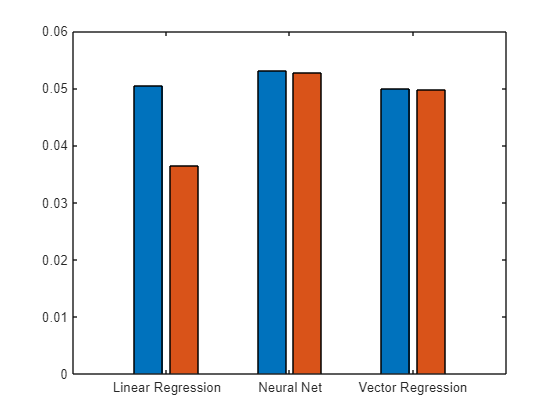

figure
bar(labels,test_res)

%Note: Orange == abs and blue == pla 

As you can see, if the material is "Pla", it will be predicted as having a higher tensile strenght on average than that of "Abs"

**Interactive Method**

You can also use [interactive machine learning algorithms](https://www.mathworks.com/campaigns/offers/next/5-interactive-apps-for-machine-learning.html) under the APPS tab to model, fit, and label data. 

function r2 = rsq(y1,y2)
    yresid = y1 - y2;
    SSresid = sum(yresid.*yresid);
    SSresid
    [V,md ] = var(y1);
    [r,c]=size(y1);
    SStotal = r*V;
    SStotal
    r2 = 1 - SSresid./SStotal;
end

% Calculate statistics
function statistics = statistics(data)
    statistics.count = numel(data); % count
    statistics.mean = mean(data); % mean
    statistics.std = std(data); % standard deviation
    statistics.min = min(data); % min
    statistics.max = max(data); % max
    statistics.Q1 = prctile(data,25); % 1st quartile (25th percentile)
    statistics.Q2 = prctile(data,50); % 2nd quartile (50th percentile) = median
    statistics.Q3 = prctile(data,75); % 3rd quartile (75th percentile)
end